|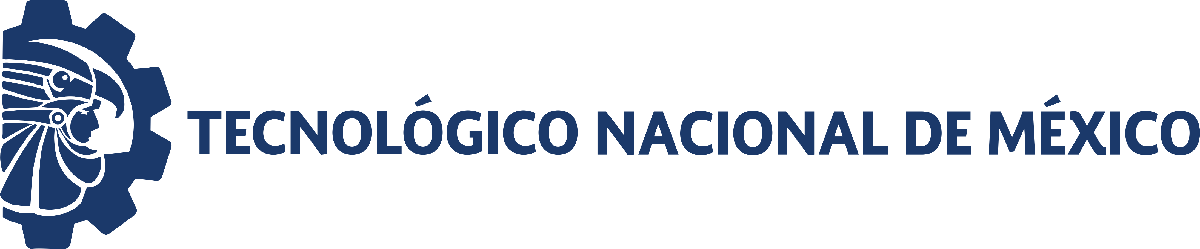                                 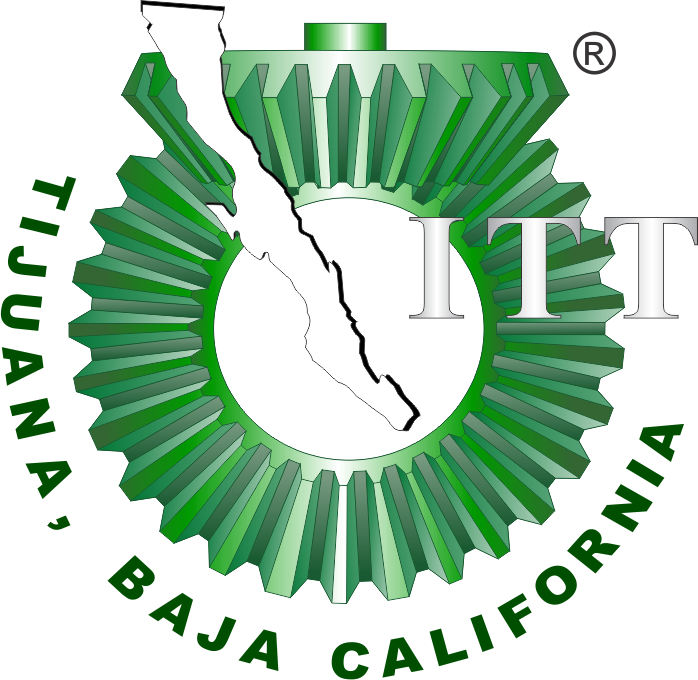

# Práctica 1: Diseño de controladores 

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general                                                                                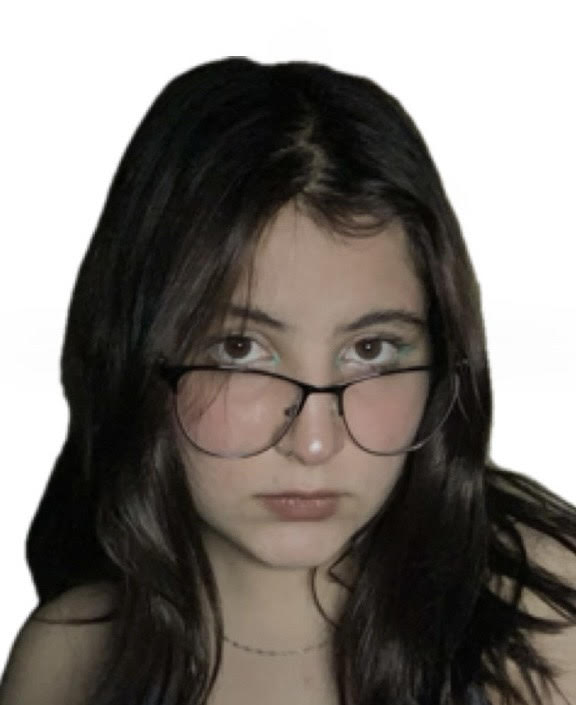

Nombre del alumno: Kenia Celeste Acosta Berrelleza 

Número de control: 22210407

Correo institucional:l22210407@tectijuana.edu.mxAsignatura:                                                                     

 **Modelado de Sistemas Fisiológicos                                                                                                              **

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend = '10';
file = 'acosta';
open_system(file);
parameters.StopTime = tend;
parameters.Solver = 'ode45';
parameters.MaxStep = '1E-3';
Controlador = 'I';

## Respuesta al escalón

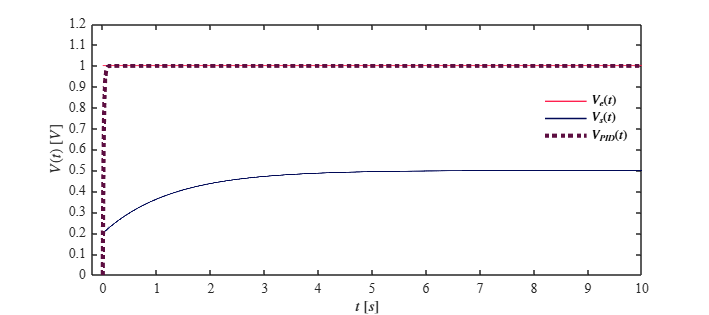

Signal = 'Escalon';
set_param('acosta/S1','sw','1');
set_param('acosta/Ve(t)','sw','1');
x1 = sim(file,parameters);
plotsignals(x1.t,x1.Ve,x1.Vs,x1.VPID,Controlador,Signal)

## Respuesta al impulso

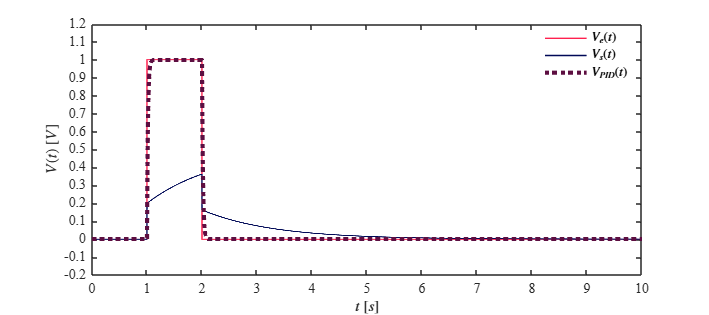

Signal = 'Impulso';
set_param('acosta/S1','sw','0');
set_param('acosta/Ve(t)','sw','1');
x2 = sim(file,parameters);
plotsignals(x2.t,x2.Ve,x2.Vs,x2.VPID,Controlador,Signal)

## Respuesta a la rampa

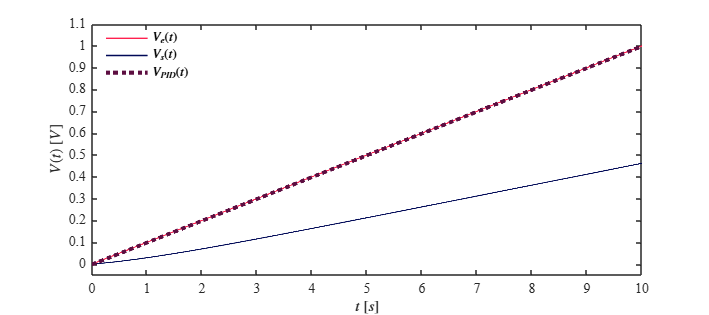

Signal = 'Rampa';
set_param('acosta/S2','sw','1');
set_param('acosta/Ve(t)','sw','0');
x3 = sim(file,parameters);
plotsignals(x3.t,x3.Ve,x3.Vs,x3.VPID,Controlador,Signal)

## Respuesta a la función sinusoidal

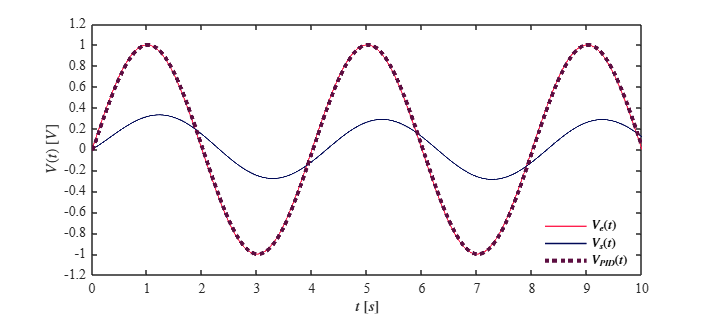

Signal = 'Sinusoidal';
set_param('acosta/S2','sw','0');
set_param('acosta/Ve(t)','sw','0');
x4 = sim(file,parameters);
plotsignals(x4.t,x4.Ve,x4.Vs,x4.VPID,Controlador,Signal)

## Funcion:Respuesta a las señales

function plotsignals(t,Ve,Vs,VPID,Controlador,Signal)
    set(figure(),'color','W')
    set(gcf,'Units','Centimeters','Position',[1,1,18,8])
    set(gca,'FontName','Times New Roman')
    fontsize(10,'points')
    rosa = [255/255, 32/255, 78/255];
    blueR = [0/255,9/255,87/255];
    morado = [93/255, 14/255, 65/255];
    hold on; grid off; box on;

    plot(t,Ve,'LineWidth',1,'Color',rosa)
    plot(t,Vs,'LineWidth',1,'Color',blueR)
    plot(t,VPID,':','LineWidth',3,'Color',morado)

    xlabel('$t$ $[s]$','Interpreter','Latex')
    ylabel('$V(t)$ $[V]$','Interpreter','Latex')

    L = legend('$V_{e}(t)$','$V_s(t)$','$V_{PID}(t)$');
    set(L,'Interpreter','Latex','Location','Best','Box','Off')

    if Signal == "Escalon"
        xlim([-0.2,10]); xticks(0:1:10)
        ylim([0,1.2]); yticks(0:0.1:1.2)

    elseif Signal == "Impulso"
         xlim([0,10]); xticks(0:1:10)
        ylim([-0.2,1.2]); yticks(-0.2:0.1:1.2)

    elseif Signal == "Rampa"
        xlim([0,10]); xticks(0:1:10)
        ylim([-0.05,1.1]); yticks(0:0.1:1.1)

    elseif Signal == "Sinusoidal"
         xlim([0,10]); xticks(0:1:10)
        ylim([-1.2,1.2]); yticks(-1.2:0.2:1.2)

    end
    exportgraphics(gcf,[Signal,'.pdf'],'ContentType','Vector')

end